% A. Engler, Vorlesung FHV, 30.04.2016
% Skript: erzeugt Zeit- und Spannungssystem
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Konstanten
TEND=0.4			% [s] Berechnungsdauer

TEND = 0.4000

SAMPLES=2000	% [1]	Anzahl der Stützstellen

SAMPLES = 2000

F=50				% [1/s] Netzfrequenz

F = 50

U1P=326			% [V] Spitzenspannung

U1P = 326

U2P=326			% [V] Spitzenspannung

U2P = 326

U3P=326			% [V] Spitzenspannung

U3P = 326

OMEGA=2*pi*F	% [1/s] Kreisfrequenz Netz

OMEGA = 314.1593

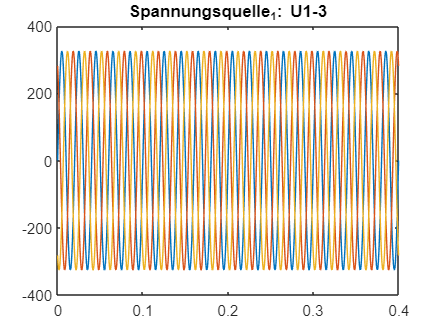

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

t=linspace(0,TEND,SAMPLES);		% Zeitbasis

% Spannungsquelle 1
u1=U1P*sin(OMEGA*t);
u2=U2P*sin(OMEGA*t+(2*pi/3));
u3=U3P*sin(OMEGA*t+(4*pi/3));
h1=figure;
plot(t,u1,t,u2,t,u3),title('Spannungsquelle_1: U1-3')


% Spannungsquelle 2
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
K1=1.05										% Änderung Spannung

K1 = 1.0500

K2=1.05										% Änderung Spannung

K2 = 1.0500

K3=1.05										% Änderung Spannung

K3 = 1.0500

PHI1=-0.1										% Änderung Winkel

PHI1 = -0.1000

PHI2=-0.1										% Änderung Winkel

PHI2 = -0.1000

PHI3=-0.1										% Änderung Winkel

PHI3 = -0.1000

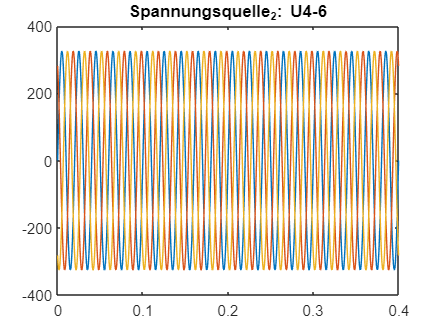

u4=K1*U1P*sin(OMEGA*t+PHI1);
u5=K2*U2P*sin(OMEGA*t+(2*pi/3)+PHI2);
u6=K3*U3P*sin(OMEGA*t+(4*pi/3)+PHI3);
h2=figure;
plot(t,u1,t,u2,t,u3),title('Spannungsquelle_2: U4-6')

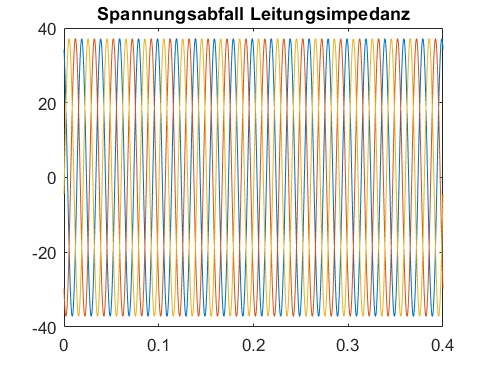


% Spannungsabfall über Leitungsimpedanz
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
delta_u1= u1 - u4;
delta_u2= u2 - u5;
delta_u3= u3 - u6;
h3=figure;
plot(t,delta_u1,t,delta_u2,t,delta_u3),title('Spannungsabfall Leitungsimpedanz')

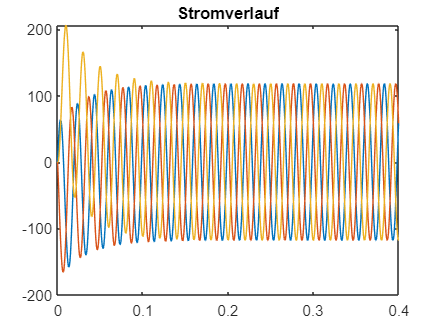


% Leistungs- und Stromberechnung
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
deltaTime = TEND/SAMPLES;
R = 30e-3;
L = 1e-3;

% Numerische Integration des Stromes
IL1 = zeros(1,SAMPLES);
IL1(1) = 0.00001;
for i=2:(SAMPLES)
    IL1(i) = IL1(i-1) + ((delta_u1(i)-IL1(i-1)*R) * deltaTime / L);
end

IL2 = zeros(1,SAMPLES);
IL2(1) = 0.00001;
for i=2:(SAMPLES)
    IL2(i) = IL2(i-1) + ((delta_u2(i)-IL2(i-1)*R) * deltaTime / L);
end

IL3 = zeros(1,SAMPLES);
IL3(1) = 0.00001;
for i=2:(SAMPLES)
     IL3(i) = IL3(i-1) + ((delta_u3(i)-IL3(i-1)*R) * deltaTime / L);
end

h4=figure;
plot(t, IL1, t, IL2, t, IL3),title('Stromverlauf')

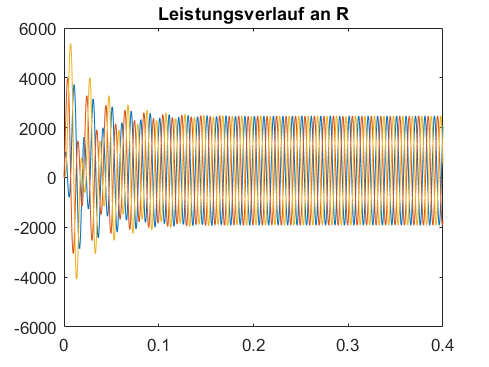


P1 = delta_u1.*IL1;
P2 = delta_u2.*IL2;
P3 = delta_u3.*IL3;

h5=figure;
plot(t, P1, t, P2, t, P3),title('Leistungsverlauf an R')


%%%%%%%%%%%%%%%% EOF